# Image

`Color Image is just a 3D Matrix containing the RED, GREEN and BLUE components in 3 different 2D Matrices.`

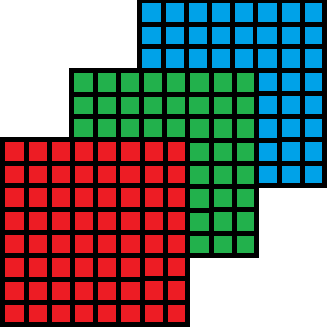

IMAGE STRUCTURE

### LOADING IMAGE

`You can load an image file into a matrix using the ``imread()`` function. This function supports ``.jpg, .png, .bmp`` and other image formats.`

I = imread('colors.png');

### DISPLAYING IMAGE

`Use the`` imshow() ``function to display an image matrix.`

imshow(I)
title("An Image File")

% IMTOOL
imtool(I)

### R G B

`Color images have separate Red, Green and Blue channels`

R = I(:, :, 1);
G = I(:, :, 2);
B = I(:, :, 3);

imshow(R);
imshow(G);
imshow(B);

### IMAGE IS JUST A MATRIX

`You can use the typical matrix operations on a image just like a regualr matrix.`

I(100:200, 100:200, :) = 0;
imshow(I)

### CROPPING

`You can use ``imcrop()`` function to crop an image.`

I = imread('shop_front.jpg');
imshow(I);

cropped = imcrop(I, [170, 100, 300, 90]);
imshow(cropped);

### RESIZING

`Use ``imresize()`` to resize an image.`

resized = imresize(cropped, [30, 100]);
imshow(resized);

### GRAYSCALE

`Grayscale images have only a single channel compared to 3 channels of an RGB image. So these images are easier to process. You can use the ``rgb2gray()`` function to do that.`

gray = rgb2gray(cropped);
imshow(gray)

### ENHANCING

`You can use the ``imadjust()`` function to adjust the contrast of the image.`

adjusted = imadjust(gray, [0.5, 1], [0, 1]);
imshow(adjusted);